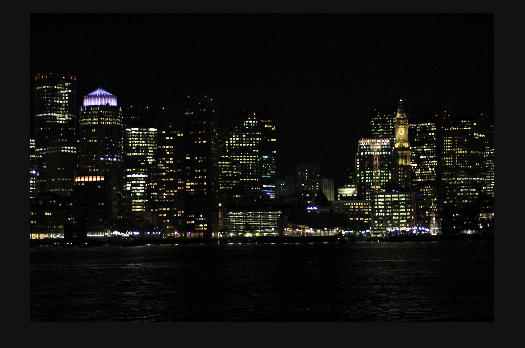

img = imread("boston night.jpg");
imgHSV = rgb2hsv(img);
val = imgHSV(:, :, 3);
imshow(img);

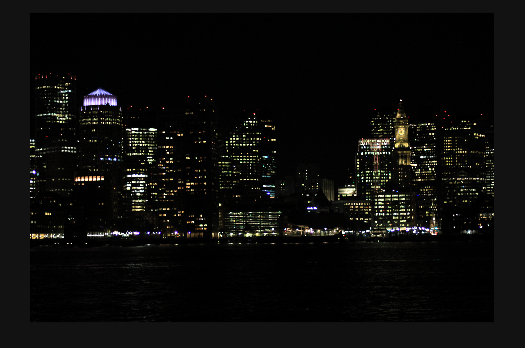

gamma = 1.3;
val0 = val;
val0 = val0 .^ gamma;
imgGamma = imgHSV;
imgGamma(:, :, 3) = val0;
imgGamma = im2uint8(hsv2rgb(imgGamma));
imshow(imgGamma);

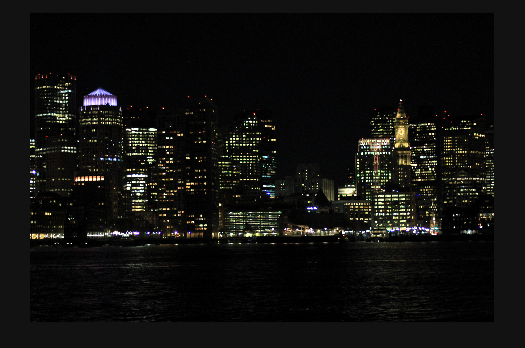

val1 = val;
val1 = imadjust(val1);
imgAdjust = imgHSV;
imgAdjust(:, :, 3) = val1;
imgAdjust = im2uint8(hsv2rgb(imgAdjust));
imshow(imgAdjust);

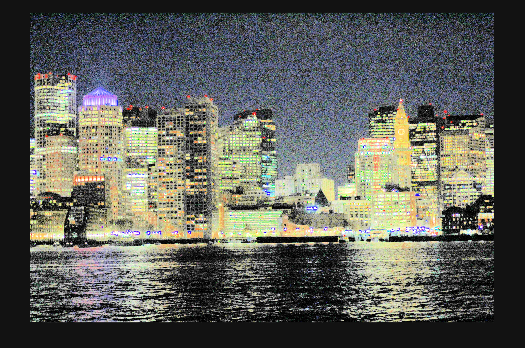

val2 = val;
val2 = histeq(val2);
imgEq = imgHSV;
imgEq(:, :, 3) = val2;
imgEq = im2uint8(hsv2rgb(imgEq));
imshow(imgEq);

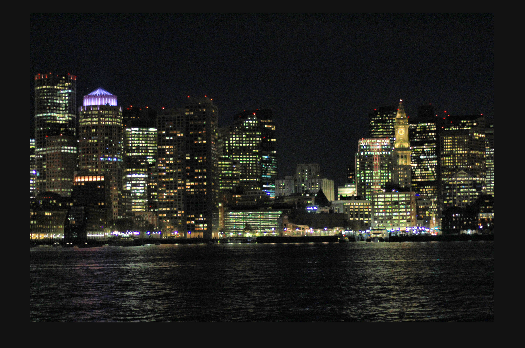

val3 = val;
val3 = adapthisteq(val3);
imgAdapt = imgHSV;
imgAdapt(:, :, 3) = val3;
imgAdapt = im2uint8(hsv2rgb(imgAdapt));
imshow(imgAdapt);

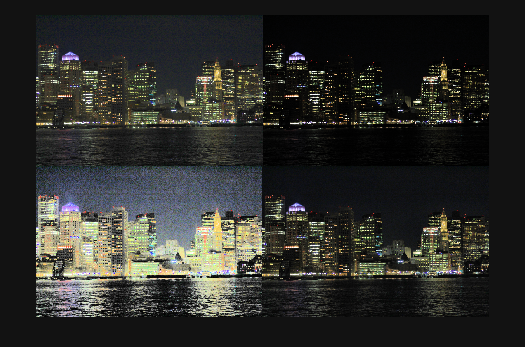

% Uncomment the below code to view four images
montage({imgGamma, imgAdjust, imgEq, imgAdapt})